close all
clear all
clc

num=[1 +1/0.8];
den=conv([1 -0.15],[1 -0.2]);
A=den;B=num;
d0=4;

Question_mark='Q32_3_J2';
for d=[2,4,5,8,10]
    n=length(A)-1;

    T_s=0.3;
    tfinal=100;
    freq=5;
    variance=0.01;
    C=0;
    dist=1

dist = 1

dist = 1

dist = 1

dist = 1

dist = 1

    [uc,t,Status,tfinal,Noix]=Datagen(0,T_s,tfinal,freq,variance,C);
    if dist==1
        Status=['_disturbed'];
    end
    Titlework=[Question_mark,Status];
    uc(1:40,1)=ones(40,1);

    N=numel(t);
    var_y=zeros(1,N);  mean_y=zeros(1,N); ACLS_y=zeros(1,N);
    var_u=zeros(1,N);  mean_u=zeros(1,N); ACLS_u=zeros(1,N);
    u=zeros(1,N);
    y=zeros(1,N);
    Normerror=0;
    Error=0;
    lambda=1;

    dg=d+length(B);
    theta_hat=zeros((n+dg),numel(t));
    theta_hat=ones((n+dg),40);
    p_per=10^8*eye(n+dg);
    for i=max(d,d0)+n:numel(t)-d
        if and(i>floor(N/3),dist==1)
            y(i)=-A(2:end)*y(i-1:-1:i-n)'+B*u(i-d0:-1:i-length(B)+1-d0)'+.1;
        else
            y(i)=-A(2:end)*y(i-1:-1:i-n)'+B*u(i-d0:-1:i-length(B)+1-d0)';
        end
        phi=[-y(i-1:-1:i-n),u(i:-1:i-d-length(B)+1)]';
        k=(p_per*phi)*(((1+phi'*p_per*phi))^-1);
        theta_hat(:,i)=theta_hat(:,i-1)+k*(y(i)-phi'*theta_hat(:,i-1));
        p=(eye(n+dg)-k*phi')*p_per;
        p_per=p;
        A_hat=[1,theta_hat(1:2,i)'];
        B_hat=(theta_hat(end-1:end,i))';
        [alpha,beta]=d_step_maker(A_hat,B_hat,d);
        u(i)=(beta(1)*(uc(i+d)-alpha*y(i:-1:i-n+1)'-beta(2:end)*u(i-1:-1:i-length(beta(2:end)))'))/(beta(1)^2+lambda);
        var_u (i)=var(u)    ;mean_u(i)=mean(u)  ;ACLS_u(i)=u(i)^2+ACLS_u(i-1)   ;
        var_y(i)=var(y)     ;mean_y(i)=mean(y)  ;ACLS_y(i)=y(i)^2+ACLS_y(i-1)   ;
        Error=(y(i)-uc(i))^2+Error;
        Normerror=norm(Error,2)+Normerror;
        if abs(u(i))>3
            u(i)=sign(u(i))*3;
        end
    end

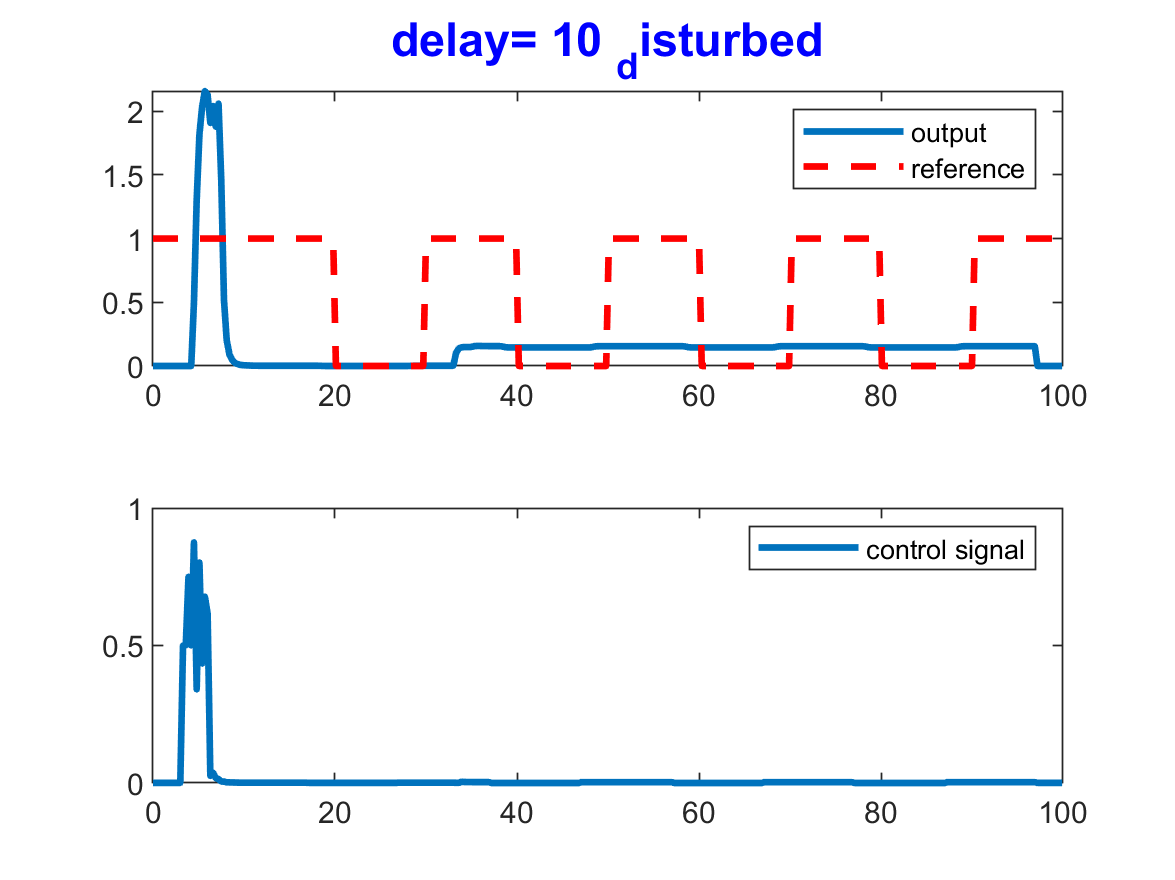

    figure(1);
    subplot(2,1,1);
    plot(t,y,t,uc','--r','linewidth',2);

    title(['delay= ',int2str(d) ,' ' Status],'Color','b','fontsize',14)
    legend('output','reference');

    subplot(212);
    plot(t,u,'linewidth',2);
    legend('control signal');
    print(gcf,[Titlework , ' d=' num2str(d) ' Result.png'],'-dpng','-r400');

    disp(['mean of u=',num2str(mean_u(end-d)),'   mean of y=',num2str(mean_y(end-d))])

mean of u=-0.038693   mean of y=-0.028212


mean of u=0.13261   mean of y=0.5247


mean of u=0.75772   mean of y=2.5106


mean of u=0.020559   mean of y=0.16143


mean of u=0.019095   mean of y=0.15665


    disp(['Error of u=',num2str(Error),'   NormError of y=',num2str(Normerror)])

Error of u=272.3981   NormError of y=55121.1191


Error of u=15.7695   NormError of y=3812.3799


Error of u=2402.3049   NormError of y=246546.1788


Error of u=131.0446   NormError of y=23676.3998


Error of u=146.1853   NormError of y=26154.635


    disp(['--------------------------------------'])

--------------------------------------


--------------------------------------


--------------------------------------


--------------------------------------


--------------------------------------


end
